# Machine Learning-Based Lithium-Ion Battery Capacity Estimation Exploiting Multi-Channel Charging Profiles

In this script, we've implemented machine learning based Lithium-Ion battery capacity estimation using multi-Channel charging Profiles. Dataset used in this example is from "Battery data set" from NASA[1].

Basic implementation theory and approach is referenced by the recent published paper[2], and they proposed Multi-Channel charging profiles based machine learning and deep learning model. Throught this example, we will capture each approach described in paper.

### Multi-Channel charging profiles of V, I, T data

To observe if charging profiles shows battery aging, we need to explore Voltage(V), Current(I) and Temperature(T) path through battery aging.

In below figure, we can observe that there are significant changes in charging profiles of V, I and T as a battery ages.

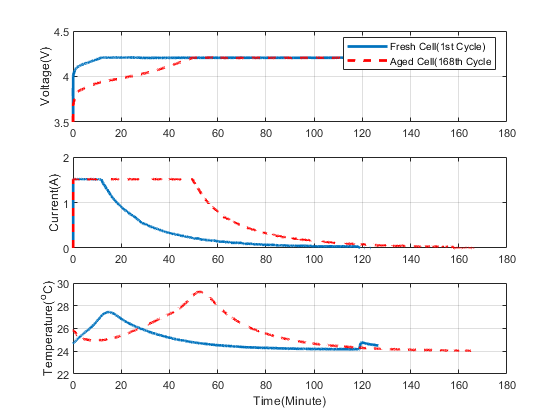

clear;
load B0005.mat
FTime = B0005.cycle(1).data.Time/60;
FreshCell_V = B0005.cycle(1).data.Voltage_measured;
FreshCell_I = B0005.cycle(1).data.Current_measured;
FreshCell_T = B0005.cycle(1).data.Temperature_measured;

ATime = B0005.cycle(168).data.Time/60;
AgedCell_V = B0005.cycle(168).data.Voltage_measured;
AgedCell_I = B0005.cycle(168).data.Current_measured;
AgedCell_T = B0005.cycle(168).data.Temperature_measured;

figure(1)
subplot(311)
plot(FTime, FreshCell_V, 'linewidth', 2), hold on, plot(ATime, AgedCell_V, 'r--','linewidth', 2)
hold off, legend('Fresh Cell(1st Cycle)', 'Aged Cell(168th Cycle'), ylabel('Voltage(V)')
ylim([3.5 4.5]), grid on
subplot(312)
plot(FTime, FreshCell_I, 'linewidth', 2), hold on, plot(ATime, AgedCell_I, 'r--', 'linewidth', 2)
hold off, ylabel('Current(A)'), ylim([0 2]), grid on
subplot(313)
plot(FTime, FreshCell_T, 'linewidth', 2), hold on, plot(ATime, AgedCell_T, 'r--', 'linewidth', 2)
hold off, ylabel('Temperature(^oC)'), ylim([22 30]), grid on, xlabel Time(Minute)

### Dataset chosen

Battery #5, #6 and #7 are chosen for the experiment. 

load B0006.mat
load B0007.mat

Eventually, we obtain four sets of battery data with degradation characteristics per cycle as below figure.

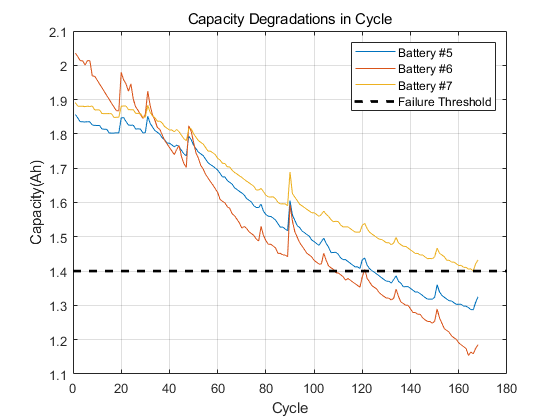

cap5 = extract_discharge(B0005);
cap6 = extract_discharge(B0006);
cap7 = extract_discharge(B0007);
figure
plot(cap5), hold on, plot(cap6), plot(cap7)
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Failure Threshold')
title('Capacity Degradations in Cycle')

### Data Preprocessing

Get ready for the training. The inputs of the proposed models in [2] are the extracted features, which are obtained by the uniform sampling of the raw battery data. Specifically, they configure the input matrix as 30-dimensional vectors by concatenating the V, I, T charging profiles, each with 10 samples. The number of samples is chosen to consider the distinct changes in time and the model complexity. In addition, we average the data over sampling interval to prevent oscillation in short time interval.

charInput5 = extract_charge_preprocessing(B0005);
charInput6 = extract_charge_preprocessing(B0006);
charInput7 = extract_charge_preprocessing(B0007);

Initial capacity for each battery data is provided as belows in the dataset:

InitC5 = 1.86;
InitC6 = 2.04;
InitC7 = 1.89;

For better training since it retains the original distribution of data except for a scaling factor and transforms all the data into the range of [0,1]:

[xB5, yB5, ym5, yr5] = minmax_norm(charInput5, InitC5, cap5);
[xB6, yB6, ym6, yr6] = minmax_norm(charInput6, InitC6, cap6);
[xB7, yB7, ym7, yr7] = minmax_norm(charInput7, InitC7, cap7);

### Machine Learning models to test

We will experiment 5 machine learning models to compare the prediction result.

Starting with FNN(Feed Forward Neural Network), we will also test CNN(Convolutional Neural Network) and LSTM(Long-Short Term Memory Network) for capacity estimation.

For FNN, we will test both for 10 and 40 hidden neurons, and also for CNN, varying the number of filter of convolution layer.

### Choose battery number to train

Since the available datasets are limited, we need to fully exploit the available datasets. Thus, out of 4 datasets, we select three battery sets as a training set and the remaining one as a test set, and repeat this process four times to have four test results. Then we average four cases of simulation to evaluate the average performance.

BatteryNum = 6;
switch BatteryNum
    case 5
        Train_Input = xB5;
        Train_Output = yB5;
        yr = yr5;
        ym = ym5;
    case 6
        Train_Input = xB6;
        Train_Output = yB6;
        yr = yr6;
        ym = ym6;
    case 7
        Train_Input = xB7;
        Train_Output = yB7;
        yr = yr7;
        ym = ym7;
end

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10);
netFNN10.trainParam.epochs = 300;
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

'local' 프로파일을 사용하여 병렬 풀(parpool)을 시작하는 중...
병렬 풀(워커 개수: 4개)에 연결되었습니다.


- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind';
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

단일 CPU에서 훈련합니다.
입력 데이터의 정규화를 초기화하는 중입니다.


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　ＲＭＳＥ　　｜　　검증　ＲＭＳＥ　　｜　　미니　배치　손실　　｜　　검증　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：０４　｜　　　　　　　　　０．７６　｜　　　　　　０．６７　｜　　　　　０．２８８２　｜　　０．２２３０　｜　　　０．００１０　｜


｜　　　　　　２５　｜　　　　　　５０　｜　　　　　００：００：０７　｜　　　　　　　　　０．２５　｜　　　　　　０．２６　｜　　　　　０．０３２０　｜　　０．０３３７　｜　　　０．００１０　｜


｜　　　　　　５０　｜　　　　　１００　｜　　　　　００：００：０８　｜　　　　　　　　　０．１９　｜　　　　　　０．１９　｜　　　　　０．０１８０　｜　　０．０１８７　｜　　　０．００１０　｜


｜　　　　　　７５　｜　　　　　１５０　｜　　　　　００：００：１０　｜　　　　　　　　　０．１６　｜　　　　　　０．１６　｜　　　　　０．０１２７　｜　　０．０１２２　｜　　　０．００１０　｜


｜　　　　　１００　｜　　　　　２００　｜　　　　　００：００：１２　｜　　　　　　　　　０．１３　｜　　　　　　０．１２　｜　　　　　０．００８３　｜　　０．００７１　｜　　　０．００１０　｜


｜　　　　　１２５　｜　　　　　２５０　｜　　　　　００：００：１４　｜　　　　　　　　　０．１１　｜　　　　　　０．０９　｜　　　　　０．００６０　｜　　０．００４０　｜　　　０．００１０　｜


｜　　　　　１５０　｜　　　　　３００　｜　　　　　００：００：１６　｜　　　　　　　　　０．１０　｜　　　　　　０．０８　｜　　　　　０．００５３　｜　　０．００３３　｜　　　０．００１０　｜


｜　　　　　１７５　｜　　　　　３５０　｜　　　　　００：００：１８　｜　　　　　　　　　０．１０　｜　　　　　　０．０８　｜　　　　　０．００４９　｜　　０．００３０　｜　　　０．００１０　｜


｜　　　　　２００　｜　　　　　４００　｜　　　　　００：００：１９　｜　　　　　　　　　０．１０　｜　　　　　　０．０７　｜　　　　　０．００４６　｜　　０．００２７　｜　　　０．００１０　｜


｜　　　　　２２５　｜　　　　　４５０　｜　　　　　００：００：２１　｜　　　　　　　　　０．０９　｜　　　　　　０．０７　｜　　　　　０．００４３　｜　　０．００２５　｜　　　０．００１０　｜


｜　　　　　２５０　｜　　　　　５００　｜　　　　　００：００：２３　｜　　　　　　　　　０．０９　｜　　　　　　０．０７　｜　　　　　０．００４０　｜　　０．００２３　｜　　　０．００１０　｜


｜　　　　　２７５　｜　　　　　５５０　｜　　　　　００：００：２５　｜　　　　　　　　　０．０８　｜　　　　　　０．０６　｜　　　　　０．００３５　｜　　０．００２１　｜　　　０．００１０　｜


｜　　　　　３００　｜　　　　　６００　｜　　　　　００：００：２７　｜　　　　　　　　　０．０８　｜　　　　　　０．０６　｜　　　　　０．００３０　｜　　０．００１８　｜　　　０．００１０　｜


｜　　　　　３２５　｜　　　　　６５０　｜　　　　　００：００：２８　｜　　　　　　　　　０．０７　｜　　　　　　０．０６　｜　　　　　０．００２５　｜　　０．００１６　｜　　　０．００１０　｜


｜　　　　　３５０　｜　　　　　７００　｜　　　　　００：００：３０　｜　　　　　　　　　０．０６　｜　　　　　　０．０５　｜　　　　　０．００２１　｜　　０．００１５　｜　　　０．００１０　｜


｜　　　　　３７５　｜　　　　　７５０　｜　　　　　００：００：３１　｜　　　　　　　　　０．０６　｜　　　　　　０．０５　｜　　　　　０．００１８　｜　　０．００１４　｜　　　０．００１０　｜


｜　　　　　４００　｜　　　　　８００　｜　　　　　００：００：３３　｜　　　　　　　　　０．０５　｜　　　　　　０．０５　｜　　　　　０．００１５　｜　　０．００１３　｜　　　０．００１０　｜


｜　　　　　４２５　｜　　　　　８５０　｜　　　　　００：００：３４　｜　　　　　　　　　０．０５　｜　　　　　　０．０５　｜　　　　　０．００１３　｜　　０．００１２　｜　　　０．００１０　｜


｜　　　　　４５０　｜　　　　　９００　｜　　　　　００：００：３６　｜　　　　　　　　　０．０５　｜　　　　　　０．０５　｜　　　　　０．００１２　｜　　０．００１１　｜　　　０．００１０　｜


｜　　　　　４７５　｜　　　　　９５０　｜　　　　　００：００：３８　｜　　　　　　　　　０．０５　｜　　　　　　０．０５　｜　　　　　０．００１１　｜　　０．００１１　｜　　　０．００１０　｜


｜　　　　　５００　｜　　　　１０００　｜　　　　　００：００：４０　｜　　　　　　　　　０．０５　｜　　　　　　０．０５　｜　　　　　０．００１１　｜　　０．００１０　｜　　　０．００１０　｜


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


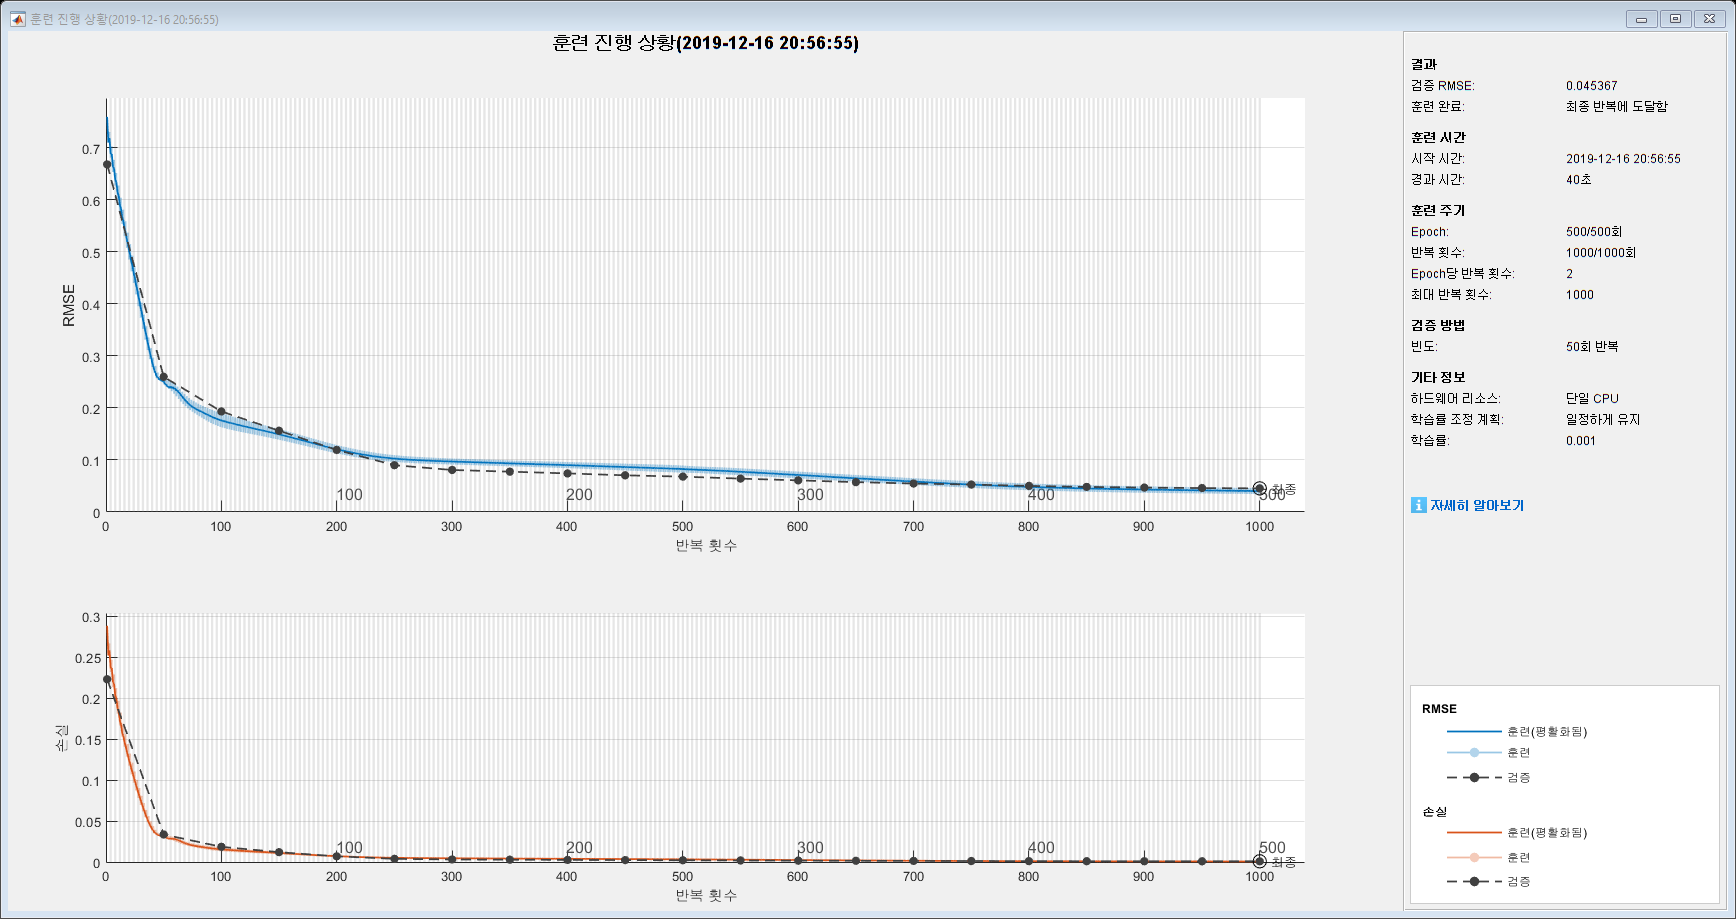

layerCNN1 = [
    imageInputLayer([1, 30]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

단일 CPU에서 훈련합니다.
입력 데이터의 정규화를 초기화하는 중입니다.


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　ＲＭＳＥ　　｜　　검증　ＲＭＳＥ　　｜　　미니　배치　손실　　｜　　검증　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：０２　｜　　　　　　　　　０．４９　｜　　　　　　０．４１　｜　　　　　０．１２１４　｜　　０．０８３２　｜　　　０．００１０　｜


｜　　　　　　２５　｜　　　　　　５０　｜　　　　　００：００：０４　｜　　　　　　　　　０．１２　｜　　　　　　０．１０　｜　　　　　０．００７４　｜　　０．００５２　｜　　　０．００１０　｜


｜　　　　　　５０　｜　　　　　１００　｜　　　　　００：００：０６　｜　　　　　　　　　０．０７　｜　　　　　　０．０６　｜　　　　　０．００２４　｜　　０．００１６　｜　　　０．００１０　｜


｜　　　　　　７５　｜　　　　　１５０　｜　　　　　００：００：０８　｜　　　　　　　　　０．０６　｜　　　　　　０．０５　｜　　　　　０．００１８　｜　　０．００１２　｜　　　０．００１０　｜


｜　　　　　１００　｜　　　　　２００　｜　　　　　００：００：１０　｜　　　　　　　　　０．０５　｜　　　　　　０．０５　｜　　　　　０．００１４　｜　　０．００１０　｜　　　０．００１０　｜


｜　　　　　１２５　｜　　　　　２５０　｜　　　　　００：００：１１　｜　　　　　　　　　０．０５　｜　　　　　　０．０４　｜　　　　　０．００１０　｜　　０．０００８　｜　　　０．００１０　｜


｜　　　　　１５０　｜　　　　　３００　｜　　　　　００：００：１３　｜　　　　　　　　　０．０４　｜　　　　　　０．０４　｜　　　　　０．０００８　｜　　０．０００８　｜　　　０．００１０　｜


｜　　　　　１７５　｜　　　　　３５０　｜　　　　　００：００：１４　｜　　　　　　　　　０．０４　｜　　　　　　０．０４　｜　　　　　０．０００６　｜　　０．０００８　｜　　　０．００１０　｜


｜　　　　　２００　｜　　　　　４００　｜　　　　　００：００：１６　｜　　　　　　　　　０．０３　｜　　　　　　０．０４　｜　　　　　０．０００６　｜　　０．０００８　｜　　　０．００１０　｜


｜　　　　　２２５　｜　　　　　４５０　｜　　　　　００：００：１７　｜　　　　　　　　　０．０３　｜　　　　　　０．０４　｜　　　　　０．０００５　｜　　０．０００８　｜　　　０．００１０　｜


｜　　　　　２５０　｜　　　　　５００　｜　　　　　００：００：１８　｜　　　　　　　　　０．０３　｜　　　　　　０．０４　｜　　　　　０．０００５　｜　　０．０００８　｜　　　０．００１０　｜


｜　　　　　２７５　｜　　　　　５５０　｜　　　　　００：００：２０　｜　　　　　　　　　０．０３　｜　　　　　　０．０４　｜　　　　　０．０００５　｜　　０．０００８　｜　　　０．００１０　｜


｜　　　　　３００　｜　　　　　６００　｜　　　　　００：００：２１　｜　　　　　　　　　０．０３　｜　　　　　　０．０４　｜　　　　　０．０００５　｜　　０．０００７　｜　　　０．００１０　｜


｜　　　　　３２５　｜　　　　　６５０　｜　　　　　００：００：２３　｜　　　　　　　　　０．０３　｜　　　　　　０．０４　｜　　　　　０．０００５　｜　　０．０００７　｜　　　０．００１０　｜


｜　　　　　３５０　｜　　　　　７００　｜　　　　　００：００：２４　｜　　　　　　　　　０．０３　｜　　　　　　０．０４　｜　　　　　０．０００４　｜　　０．０００７　｜　　　０．００１０　｜


｜　　　　　３７５　｜　　　　　７５０　｜　　　　　００：００：２５　｜　　　　　　　　　０．０３　｜　　　　　　０．０４　｜　　　　　０．０００４　｜　　０．０００７　｜　　　０．００１０　｜


｜　　　　　４００　｜　　　　　８００　｜　　　　　００：００：２７　｜　　　　　　　　　０．０３　｜　　　　　　０．０４　｜　　　　　０．０００４　｜　　０．０００７　｜　　　０．００１０　｜


｜　　　　　４２５　｜　　　　　８５０　｜　　　　　００：００：２８　｜　　　　　　　　　０．０３　｜　　　　　　０．０４　｜　　　　　０．０００４　｜　　０．０００７　｜　　　０．００１０　｜


｜　　　　　４５０　｜　　　　　９００　｜　　　　　００：００：２９　｜　　　　　　　　　０．０３　｜　　　　　　０．０４　｜　　　　　０．０００４　｜　　０．０００７　｜　　　０．００１０　｜


｜　　　　　４７５　｜　　　　　９５０　｜　　　　　００：００：３１　｜　　　　　　　　　０．０３　｜　　　　　　０．０４　｜　　　　　０．０００４　｜　　０．０００７　｜　　　０．００１０　｜


｜　　　　　５００　｜　　　　１０００　｜　　　　　００：００：３２　｜　　　　　　　　　０．０３　｜　　　　　　０．０４　｜　　　　　０．０００４　｜　　０．０００７　｜　　　０．００１０　｜


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


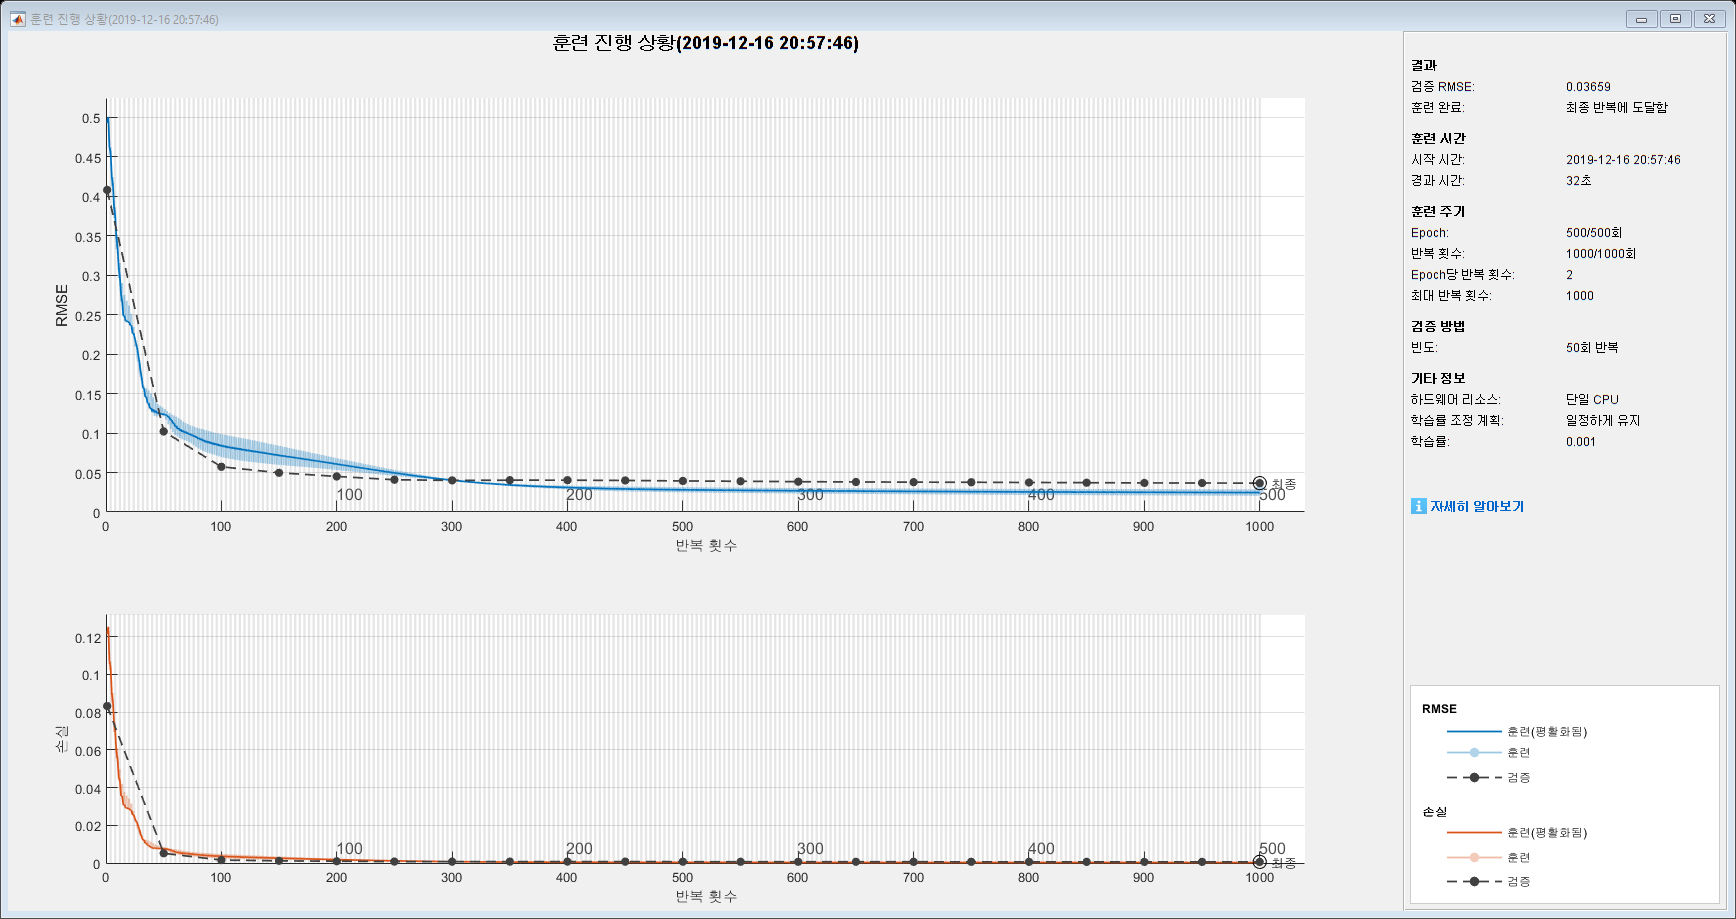

layerCNN2 = [
    imageInputLayer([1, 30]);
    convolution2dLayer([1, 2], 30, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 15, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 5 hidden units

단일 CPU에서 훈련합니다.


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　ＲＭＳＥ　　｜　　검증　ＲＭＳＥ　　｜　　미니　배치　손실　　｜　　검증　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：０２　｜　　　　　　　　　０．４７　｜　　　　　　０．４１　｜　　　　　０．１０８６　｜　　０．０８２７　｜　　　０．００１０　｜


｜　　　　　　２５　｜　　　　　　５０　｜　　　　　００：００：０３　｜　　　　　　　　　０．１８　｜　　　　　　０．１６　｜　　　　　０．０１５６　｜　　０．０１３０　｜　　　０．００１０　｜


｜　　　　　　５０　｜　　　　　１００　｜　　　　　００：００：０４　｜　　　　　　　　　０．１５　｜　　　　　　０．１２　｜　　　　　０．０１１４　｜　　０．００７５　｜　　　０．００１０　｜


｜　　　　　　７５　｜　　　　　１５０　｜　　　　　００：００：０５　｜　　　　　　　　　０．１３　｜　　　　　　０．０９　｜　　　　　０．００８５　｜　　０．００３９　｜　　　０．００１０　｜


｜　　　　　１００　｜　　　　　２００　｜　　　　　００：００：０７　｜　　　　　　　　　０．１２　｜　　　　　　０．０７　｜　　　　　０．００７２　｜　　０．００２７　｜　　　０．００１０　｜


｜　　　　　１２５　｜　　　　　２５０　｜　　　　　００：００：０８　｜　　　　　　　　　０．１１　｜　　　　　　０．０７　｜　　　　　０．００６４　｜　　０．００２３　｜　　　０．００１０　｜


｜　　　　　１５０　｜　　　　　３００　｜　　　　　００：００：０９　｜　　　　　　　　　０．１１　｜　　　　　　０．０６　｜　　　　　０．００５６　｜　　０．００２１　｜　　　０．００１０　｜


｜　　　　　１７５　｜　　　　　３５０　｜　　　　　００：００：１０　｜　　　　　　　　　０．１０　｜　　　　　　０．０６　｜　　　　　０．００４９　｜　　０．００１９　｜　　　０．００１０　｜


｜　　　　　２００　｜　　　　　４００　｜　　　　　００：００：１１　｜　　　　　　　　　０．０９　｜　　　　　　０．０６　｜　　　　　０．００４１　｜　　０．００１７　｜　　　０．００１０　｜


｜　　　　　２２５　｜　　　　　４５０　｜　　　　　００：００：１２　｜　　　　　　　　　０．０８　｜　　　　　　０．０６　｜　　　　　０．００３４　｜　　０．００１５　｜　　　０．００１０　｜


｜　　　　　２５０　｜　　　　　５００　｜　　　　　００：００：１３　｜　　　　　　　　　０．０８　｜　　　　　　０．０５　｜　　　　　０．００２８　｜　　０．００１４　｜　　　０．００１０　｜


｜　　　　　２７５　｜　　　　　５５０　｜　　　　　００：００：１４　｜　　　　　　　　　０．０７　｜　　　　　　０．０５　｜　　　　　０．００２４　｜　　０．００１２　｜　　　０．００１０　｜


｜　　　　　３００　｜　　　　　６００　｜　　　　　００：００：１５　｜　　　　　　　　　０．０６　｜　　　　　　０．０５　｜　　　　　０．００２０　｜　　０．００１１　｜　　　０．００１０　｜


｜　　　　　３２５　｜　　　　　６５０　｜　　　　　００：００：１６　｜　　　　　　　　　０．０６　｜　　　　　　０．０４　｜　　　　　０．００１８　｜　　０．００１０　｜　　　０．００１０　｜


｜　　　　　３５０　｜　　　　　７００　｜　　　　　００：００：１７　｜　　　　　　　　　０．０６　｜　　　　　　０．０４　｜　　　　　０．００１６　｜　　０．０００９　｜　　　０．００１０　｜


｜　　　　　３７５　｜　　　　　７５０　｜　　　　　００：００：１８　｜　　　　　　　　　０．０５　｜　　　　　　０．０４　｜　　　　　０．００１４　｜　　０．０００９　｜　　　０．００１０　｜


｜　　　　　４００　｜　　　　　８００　｜　　　　　００：００：１８　｜　　　　　　　　　０．０５　｜　　　　　　０．０４　｜　　　　　０．００１３　｜　　０．０００８　｜　　　０．００１０　｜


｜　　　　　４２５　｜　　　　　８５０　｜　　　　　００：００：１９　｜　　　　　　　　　０．０５　｜　　　　　　０．０４　｜　　　　　０．００１２　｜　　０．０００８　｜　　　０．００１０　｜


｜　　　　　４５０　｜　　　　　９００　｜　　　　　００：００：２０　｜　　　　　　　　　０．０５　｜　　　　　　０．０４　｜　　　　　０．００１２　｜　　０．０００８　｜　　　０．００１０　｜


｜　　　　　４７５　｜　　　　　９５０　｜　　　　　００：００：２１　｜　　　　　　　　　０．０５　｜　　　　　　０．０４　｜　　　　　０．００１１　｜　　０．０００７　｜　　　０．００１０　｜


｜　　　　　５００　｜　　　　１０００　｜　　　　　００：００：２２　｜　　　　　　　　　０．０５　｜　　　　　　０．０４　｜　　　　　０．００１１　｜　　０．０００７　｜　　　０．００１０　｜


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


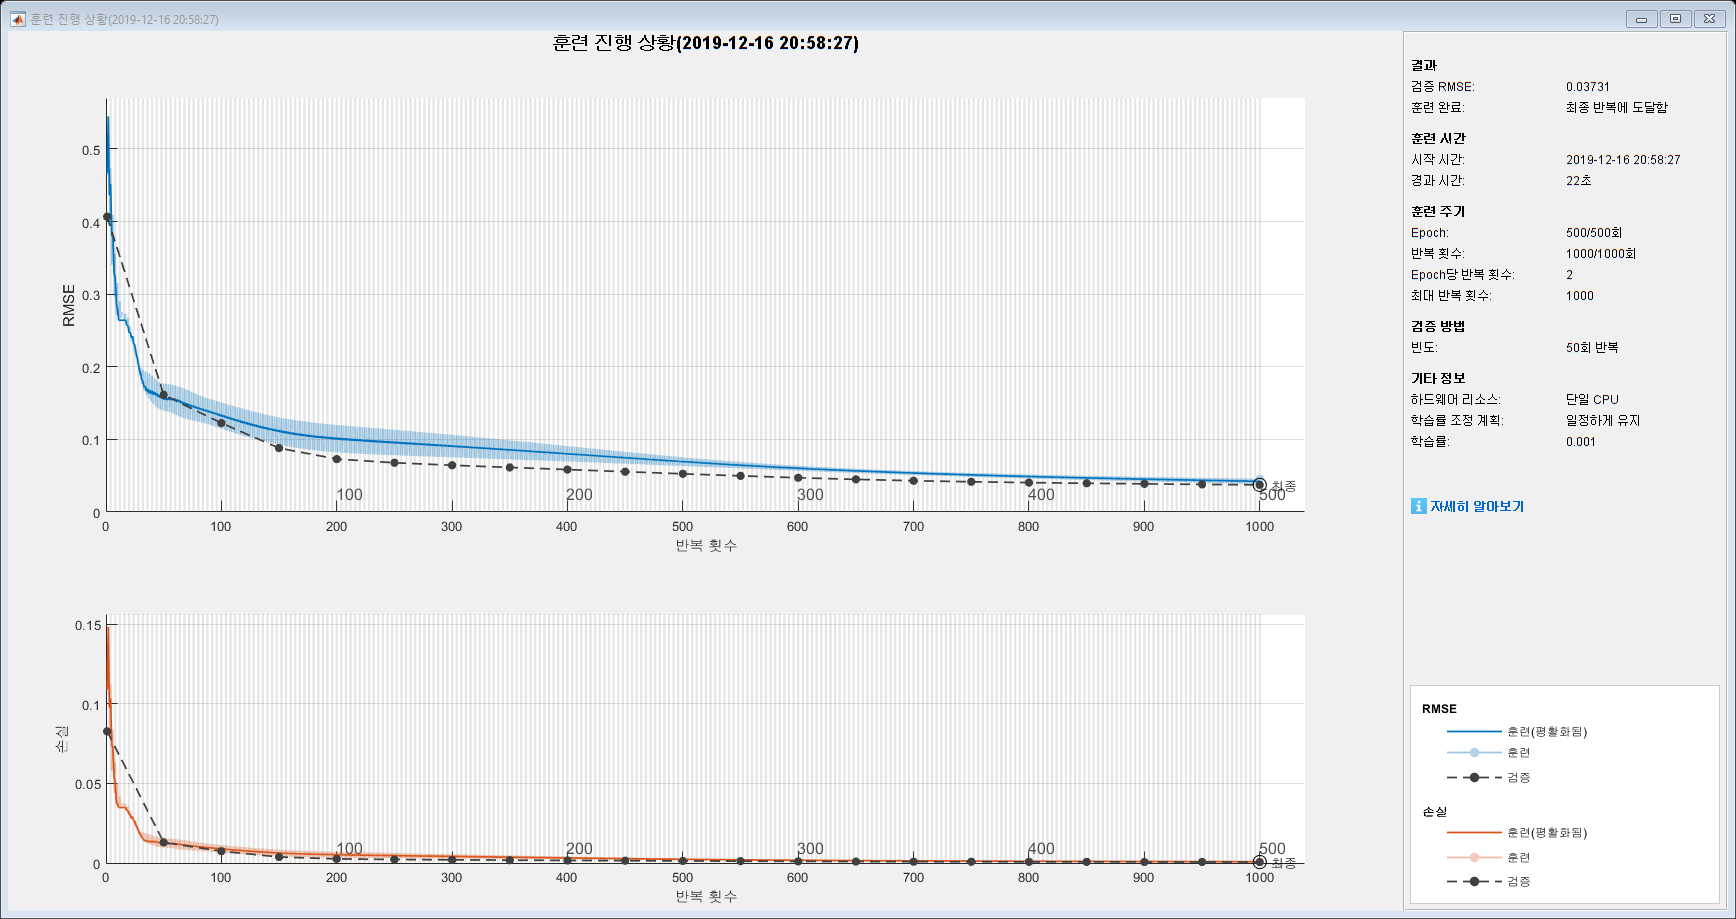

inputSize = 30;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

### Prediciton using each 5 trained model

Make a prediction using trained models

- FNN10

pFNN10 = netFNN10(Train_Input(tr.testInd, :)');

- FNN40

pFNN40 = netFNN40(Train_Input(tr.testInd, :)');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(Train_Input(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, 30, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM, num2cell(Train_Input(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

Train_Output = Train_Output(tr.testInd, :)*yr + ym;
pFNN10 = pFNN10*yr+ ym;
pFNN40 = pFNN40*yr + ym;
pCNN1 = pCNN1*yr + ym;
pCNN2 = pCNN2*yr + ym;
pLSTM = pLSTM*yr + ym;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

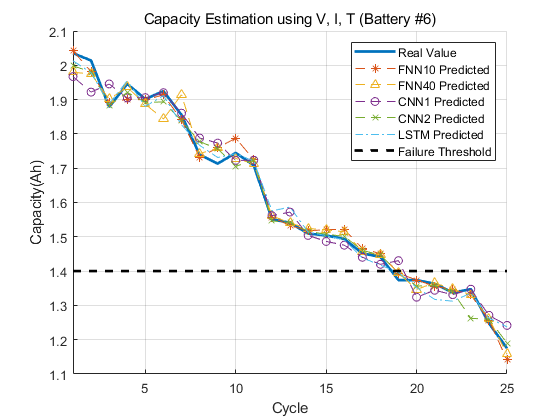

figure, hold on, grid on,
plot(Train_Output, 'linewidth', 2), plot(pFNN10, '*--'), plot(pFNN40, '^--'), plot(pCNN1, 'o--'), plot(pCNN2, 'x--'), plot(pLSTM, '-.')
plot(1:25, 1.4*ones(1, 25),'k--','LineWidth', 2), xlim([1 25])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN10 Predicted', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted', 'Failure Threshold')

[1] B. Saha and K. Goebel, ``Battery data set,''NASA AMES Prognostics Data Repository, 2007.

[2] Choi, Yohwan, et al. "Machine Learning-Based Lithium-Ion Battery Capacity Estimation Exploiting Multi-Channel Charging Profiles." *IEEE Access* 7 (2019): 75143-75152.

***Copyright 2019 The MathWorks, Inc.***